# Normalised firing rate as feature space

clear variables;

load('monkeydata_training');

data = section(trial);

for i = 1:1:98
    p(i) = tuning_curve(data,i,5,'count','');
end

peaks = extractfield(p,'values');
peaks = peaks(1:8,:);
s = sum(peaks,1);
peaks = peaks./s;


Select three angles

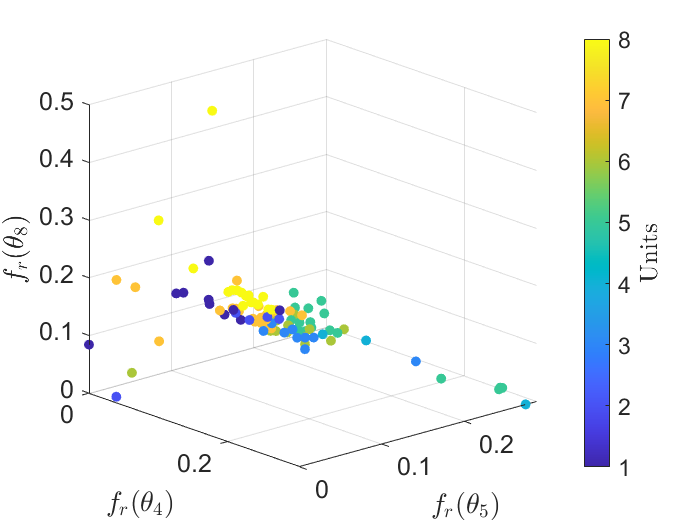

ang(1)=false; ang(2)=false; ang(3)=false; ang(4)=true; 
ang(5)=true; ang(6)=false; ang(7)=false; ang(8)=true;

[~,ang] = find(ang==1);

p = extractfield(p,'idx');
c = p(1,:);
scatter3(peaks(ang(1),:),peaks(ang(2),:),peaks(ang(3),:),[],c,'filled');
set(gca,'FontSize',15);
xlabel(sprintf('$$f_r(\\theta_%d)$$',ang(1)),'FontSize',20);
ylabel(sprintf('$$f_r(\\theta_%d)$$',ang(2)),'FontSize',20);
zlabel(sprintf('$$f_r(\\theta_%d)$$',ang(3)),'FontSize',20);
col = colorbar;
col.Label.String = 'Units';
col.Label.FontSize = 15;
col.Label.Interpreter = 'latex';